close all;
clear variables;
clc;

## Reading training, validation and test image names from text files

folder = "CUB_200_2011";
trainingImageNames = readtable(fullfile(folder, "train200.txt"),'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(fullfile(folder, "validate200.txt"),'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(fullfile(folder, "test200.txt"),'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Reading class names and image class labels from text files

classNames = readtable(fullfile(folder, "classes.txt"),'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(fullfile(folder, "image_class_labels.txt"),'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Creating training, validation and test subset lists of image names

folder = "CUB_200_2011/";
trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Creating training, validation and test subset image datastores

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;

validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;

testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;

countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  


countEachLabel(testImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## Standardising the image sizes for ease of analysis and comparison

% target_size = [100, 100];
target_size = [224, 224];

% resizing using transform operation
training_image_datastore_resized = transform(trainingImageDS, @(image_i) imresize(image_i,target_size));
validation_image_datastore_resized = transform(validationImageDS, @(image_i) imresize(image_i,target_size));
test_image_datastore_resized = transform(testImageDS, @(image_i) imresize(image_i,target_size));

% Combine transformed datastores and labels
training_labels = arrayDatastore(trainingImageDS.Labels);
training_combined_datastore = combine(training_image_datastore_resized, training_labels);

validation_labels = arrayDatastore(validationImageDS.Labels);
validation_combined_datastore = combine(validation_image_datastore_resized, validation_labels);

test_labels = arrayDatastore(testImageDS.Labels);
test_combined_datastore = combine(test_image_datastore_resized, test_labels);

% % cnn architecture 
% % number_of_layers = 3;
% % number_of_layers = 4;
% % number_of_layers = 5;
% number_of_layers = 6;
% 
% layers = [
%     imageInputLayer([224 224 3])
%     
%     % First convolutional block
%     convolution2dLayer(3, 8, 'Padding', 'same')
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2, 'Stride', 2)
%     
%     % Second convolutional block
%     convolution2dLayer(3, 16, 'Padding', 'same')
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2, 'Stride', 2)
%     
%     % Third convolutional block
%     convolution2dLayer(3, 32, 'Padding', 'same')
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2, 'Stride', 2)
% 
%     % Fourth convolutional block
%     convolution2dLayer(3, 64, 'Padding', 'same')
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2, 'Stride', 2)
% 
%     % Fifth convolutional block
%     convolution2dLayer(3, 128, 'Padding', 'same')
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2, 'Stride', 2)
% 
%     % Sixth convolutional block
%     convolution2dLayer(3, 256, 'Padding', 'same')
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2, 'Stride', 2)
% 
%     % Fully connected block
%     fullyConnectedLayer(512)
%     batchNormalizationLayer
%     reluLayer
%     dropoutLayer(0.5)
%     
%     fullyConnectedLayer(256)
%     batchNormalizationLayer
%     reluLayer
%     dropoutLayer(0.5)
%     
%     fullyConnectedLayer(20)
%     softmaxLayer
%     classificationLayer];
trainedNetwork = resnet50;
analyzeNetwork(trainedNetwork);

% when we analyze the network the first layer will mention the input size
% for resnet 50 it's 224 224
lgraph = layerGraph(trainedNetwork);
deltafc1000 = fullyConnectedLayer(200,'Name','dfc1000');
deltaClassificationfc1000 = classificationLayer('Name', 'dcfc1000', 'Classes', 'auto');
lgraph = replaceLayer(lgraph,'fc1000',deltafc1000);
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',deltaClassificationfc1000);

## Checking if a GPU is available and clearing any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    gpu_device = gpuDevice(1);
    reset(gpu_device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index                     Name                      ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _______________________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3050 Ti Laptop GPU"          "8.6"               true              false     



## Training a multi-class SVM

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:46 |        0.00% |        0.55% |       5.6526 |       5.7379 |          0.0010 |
|       1 |           2 |       00:00:47 |        0.00% |              |       5.8694 |              |          0.0010 |
|       1 |           3 |       00:00:48 |        0.00% |              |       5.7130 |              |          0.0010 |
|       1 |           4 |       00:00:48 |        0.00% |              |       5.5154 |   

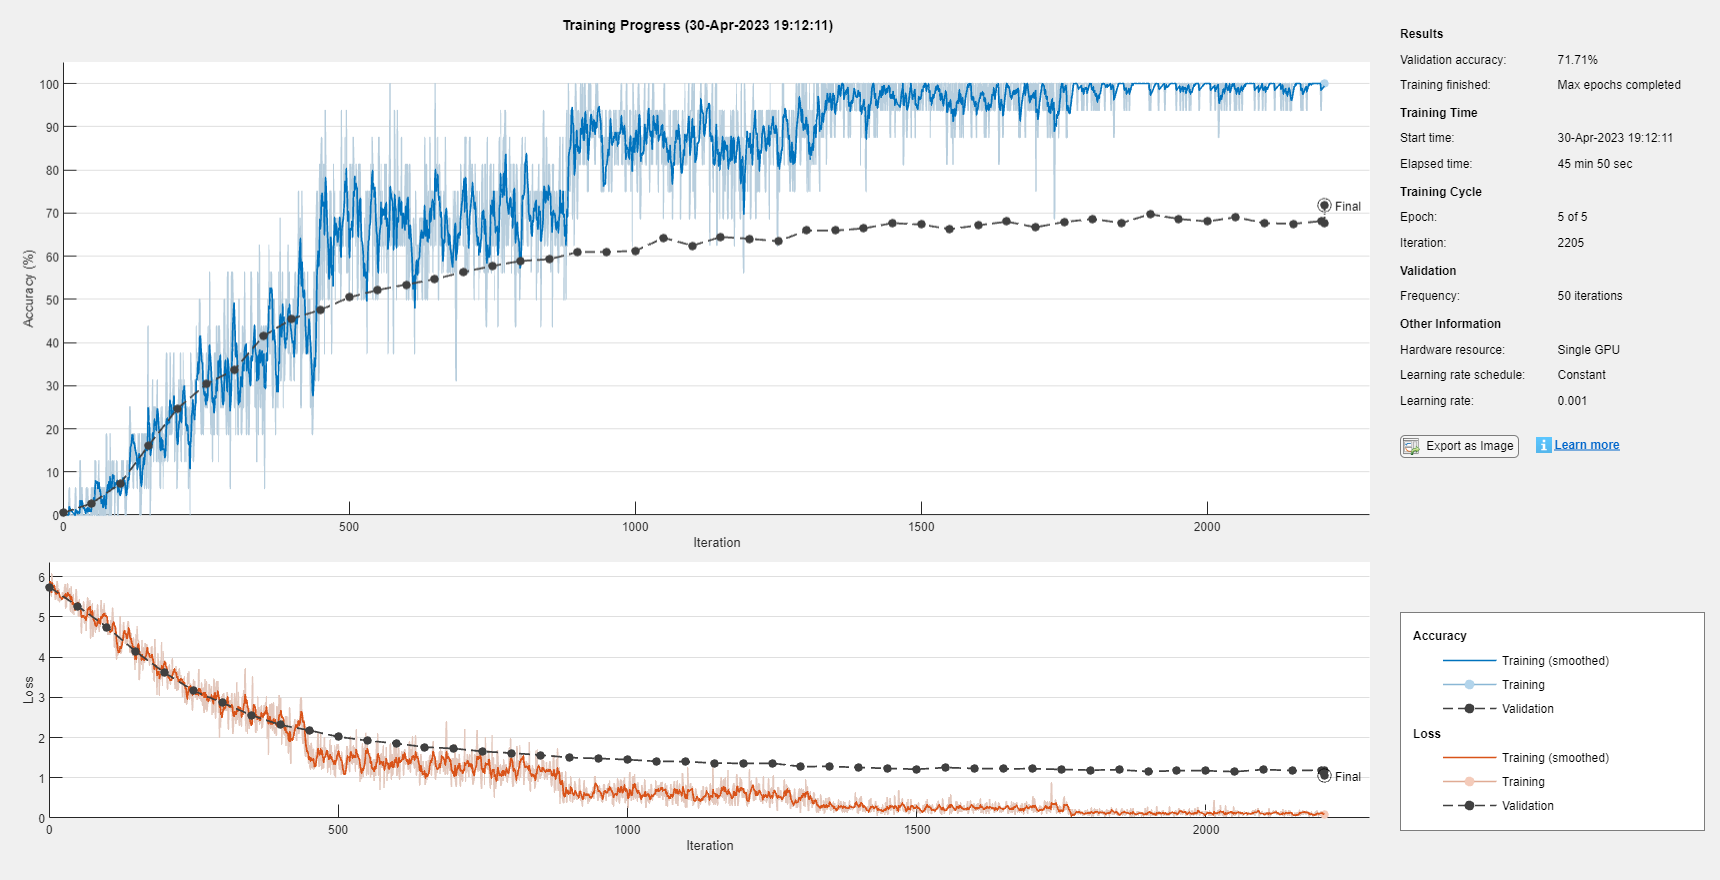

% learning_rate = 0.01;
learning_rate = 0.001;
% learning_rate = 0.0001;

% batch_size = 8;
batch_size = 16;
% batch_size = 32;

epochs = 5;
% epochs = 10;
% epochs = 20;

options = trainingOptions('sgdm', ...
        'InitialLearnRate', learning_rate, ...
        'MiniBatchSize', batch_size, ...
        'MaxEpochs', epochs, ...
        'Verbose', true, ...
        'Shuffle', 'every-epoch', ...
        'VerboseFrequency', 1, ...
        'ValidationData', validation_combined_datastore, ...
        'Plots','training-progress');

myCNN = trainNetwork(training_combined_datastore, lgraph, options);

## Test the accuracy on the test partition

target_predictions = classify(myCNN, test_image_datastore_resized);
target_test = testImageDS.Labels;

% Calculate overall accuracy
overall_accuracy = sum(target_predictions == target_test)/numel(target_test) % Output on command line

overall_accuracy = 0.7106

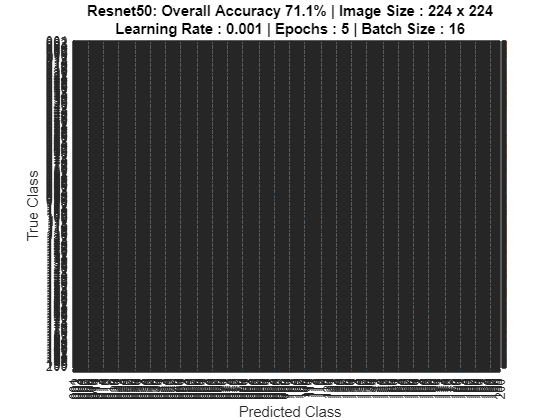


% Show confusion matrix in figure
[matrix, order] = confusionmat(target_test, target_predictions);
figure(2);
confusion_matrix = confusionchart(matrix, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title({"Resnet50: Overall Accuracy " + string(round(overall_accuracy*100, 1)) + "%" + ...
    " | Image Size : " + target_size(1) + " x " + target_size(1); ...
    "Learning Rate : " + learning_rate + " | Epochs : " + epochs + " | Batch Size : " + batch_size})

class_wise_correct_recognition_rates = zeros(height(order), 1);
samples_per_row = sum(matrix, 2);
for i = 1:height(order)
    class_wise_correct_recognition_rates(i) = round(100 * matrix(i, i) / samples_per_row(i), 1);
end
class_name_labels = table2array(classNames(:,2));

class_wise_recognition_rates = table(class_name_labels, ...
    class_wise_correct_recognition_rates, ...
    'VariableNames',["Class Name", "Correct Recognition Rate (%)"]);

disp("Class Weighted Average Overall Accuracy is " + string(round(overall_accuracy*100, 2)) + "%");

Class Weighted Average Overall Accuracy is 71.06%


disp(class_wise_recognition_rates);

                  Class Name                  Correct Recognition Rate (%)
    ______________________________________    ____________________________

    {'001.Black_footed_Albatross'        }                66.7            
    {'002.Laysan_Albatross'              }                  50            
    {'003.Sooty_Albatross'               }                63.6            
    {'004.Groove_billed_Ani'             }                66.7            
    {'005.Crested_Auklet'                }                77.8            
    {'006.Least_Auklet'                  }                62.5            
    {'007.Parakeet_Auklet'               }                91.7            
    {'008.Rhinoceros_Auklet'             }                55.6            
    {'009.Brewer_Blackbird'              }                41.7            
    {'010.Red_winged_Blackbird'          }                 100            
    {'011.Rusty_Blackbird'     